%15 miunte single plots

% Clear workspace and command window
clear;
clc;

% Read data from the Excel file
drip_data = readtable('COMBINATIONJANMAY2024_cleanMay16NEW.xlsx');

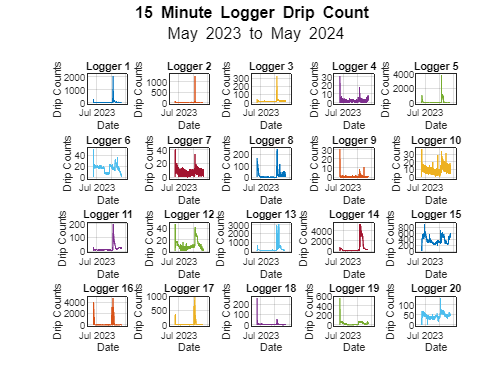

%water_budget = readtable('Copy_of_Rainfall_Loggers_PET_monthly_SUM.csv'); 

% Extract dates, and drip count data
d_dates = drip_data {:, 1}; %time is in column 1
drip_count = drip_data{:, 2:end}; % Drip count is in columns 3 to 22

%w_dates= water_budget {:, 1}; %Date is in column 1
%p_et= water_budget{:, 4}; % P-ET is in columns 4

% Create a figure for subplots
figure; clf
tiledlayout(4,5, 'TileSpacing','tight');

% Define a set of colors (20 unique colors)
colors = lines(20);  % Use MATLAB's 'lines' colormap, which generates distinct colors

for i = 1:20
     subplot(4,5,i);% Create a 5x4 grid of subplots
plot (d_dates, drip_count(:, i),'Color', colors(i, :)); % Plot the data for the ith logger   
xlabel('Date');% X-axis label
ylabel('Drip Counts');% Y-axis label
 title(['Logger ' num2str(i)]); % Title for each subplot

grid on % Add a grid to the plot
axis padded
% hold off
end

% % Bar plot for the reduced subplot
% subplot(7, 3, 21); % Position the bar plot in position 21
% bar((1:13), p_et); % P-ET data
% xlabel('Months');
% ylabel('Water Budget (mm)');
% title('Monthly P-ET');
% xtickangle(90);
% xtick = {'May 23'; 'Jun 23'; 'Jul 23'; 'Aug 23'; 'Sep 23'; 'Oct 23'; 'Nov 23'; 'Dec 23'; 'Jan 24'; 'Feb 24'; 'Mar 24'; 'Apr 24'; 'May 24'};
% set(gca, 'XTick', 1:1:13); % Set x-axis ticks at positions 1 through 13
% set(gca, 'XTickLabel', xtick); % Set x-axis labels
% grid on;
% axis padded

% Create sgtitle after adjusting subplot layout
sgtitle({'\bf15 Minute Logger Drip Count', ' May 2023 to May 2024'});



%saveas(gcf, '15min_drip_count_plot_colour.png');  % Saves the current figure as 'drip_count_plot.png' in the current directory
%exportgraphics(gcf, '15min_drip_count_plot_coloured.png', 'Resolution', 1500);  % Saves the figure with 500 DPI resolution

